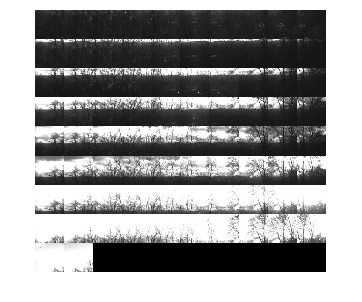

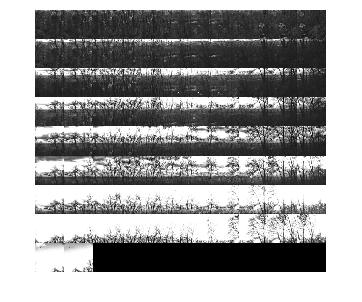

%% Run mask/crop/adapthisteq pipeline
inputDir = uigetdir("Title", "Please select the Concrete Registration folder in your course files.");
if isequal(inputDir, 0)
    error("No folder selected.");
end

maskDir = fullfile(fileparts(pwd), "matlab_roi_extraction");
saveDir = mask_crop_adapthisteq_pipeline(string(inputDir), ...
    "MaskSearchDir", string(maskDir), ...
    "ShowPreview", true, ...
    "MaxPreview", 16);

fprintf("Saved preprocessed images to: %s\\n", saveDir);